mandelPoints = fWithoutgMandelbrotCeiling(5000, 4000, 10000)

mandelPoints2 = fWithoutgMandelbrotCeiling(100, 20000, 10000)

%mandelPoints3 = fWithoutgMandelbrot(10000, 1000)

%fixedPoints = fFixedWithoutgFixed(800, 2000, 10000)

length = 100000;
[orbitf, orbitg] = matrixOrbit(mandelPoints2', length)

mandelPoints4 = fWithoutgMandelbrotCeiling(100, 20000, 10000)
length = 100000;
[orbitf, orbitg] = matrixOrbit(mandelPoints4', length)

c = nan;
length = 1000;

[orbitf, orbitg, orbith, orbitm, orbitn, fixedPoints] = orbitCalc(length, c);

c = -1.0000 - 0.2714i

maxNorm = 1.1773

index = 4

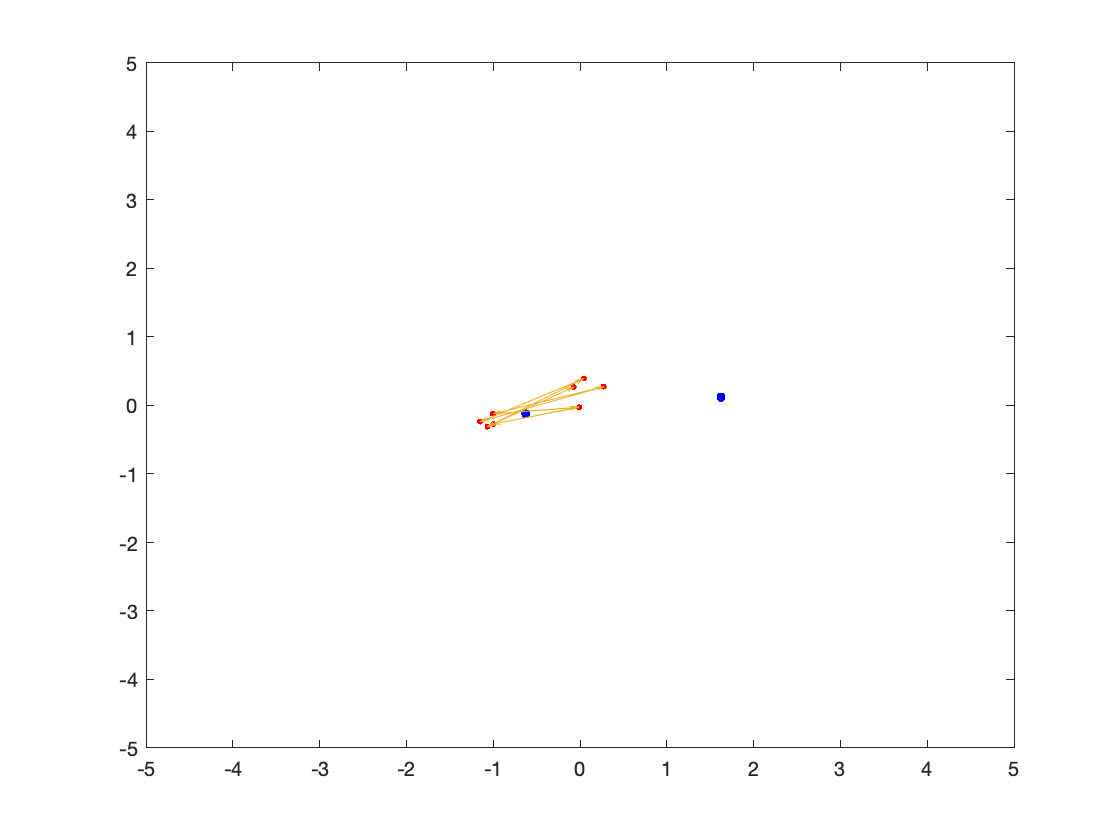


orbit = orbitf;
val = 5;
corners = [-val val -val val];

orbitPlotter(orbit, fixedPoints, corners)

function output = coloredMandelbrotg(max_iter, res, ceiling)
    x = linspace(-2, 1, res);
    y = linspace(-1.5, 1.5, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    hsv_image = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n = 0;
            z1 = c;
            z2 = 1;
            while abs(z2) < ceiling && n < max_iter
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n = n + 1;
            end
            if n < max_iter
                hsv_image(k, j, 3) = 1;
            else
                n = max_iter;
                hsv_image(k, j, 3) = 0;
            end
            hsv_image(k, j, 1) = n / max_iter;
            hsv_image(k, j, 2) = 1;
        end
    end
    rgb_image = hsv2rgb(hsv_image);
    imshow(rgb_image)
end

function output = fWithoutgMandelbrotCeiling(max_iter, res, ceiling)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    x_axis = [];
    y_axis = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n1 = 0;
            n2 = 0;
            z1 = c;
            z2 = 1;
            z3 = c;
            while n1 < max_iter && abs(z2) < ceiling
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n1 = n1 + 1;
            end
            while n2 < max_iter && abs(z3) < 2
                z3 = f(z3, c);
                n2 = n2 + 1;
            end
            if n2 == max_iter && n1 < max_iter
                x_axis = [x_axis x(j)];
                y_axis = [y_axis y(k)];
            end
        end
    end
    %scatter(x_axis, y_axis, 1, 'filled')
    output = x_axis + y_axis*1i;
end

function output = fWithoutgMandelbrot(max_iter, res)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    x_axis = [];
    y_axis = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n1 = 0;
            n2 = 0;
            z1 = c;
            z2 = 1;
            z3 = c;
            while n1 < max_iter & ~isinf(abs(z2))
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n1 = n1 + 1;
            end
            while n2 < max_iter && abs(z3) < 2
                z3 = f(z3, c);
                n2 = n2 + 1;
            end
            if n2 == max_iter && n1 < max_iter
                x_axis = [x_axis x(j)];
                y_axis = [y_axis y(k)];
            end
        end
    end
    scatter(x_axis, y_axis, 1, 'filled')
    output = x_axis + y_axis*1i;
end

function output = fFixedWithoutgFixed(max_iter, res, ceiling)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    x_fixed = [];
    y_fixed = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n1 = 0;
            n2 = 0;
            z1 = c;
            z2 = 1;
            z3 = c;
            while n1 < max_iter && abs(z2) < ceiling
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n1 = n1 + 1;
            end
            while n2 < max_iter && abs(z3) < 2
                z3 = f(z3, c);
                n2 = n2 + 1;
            end
            if n2 == max_iter && n1 < max_iter
                alpha_neg = (1 - sqrt(1 - 4 * c)) / 2;
                alpha_pos = (1 + sqrt(1 - 4 * c)) / 2;
                x_fixed = [x_fixed real(alpha_pos) real(alpha_neg)];
                y_fixed = [y_fixed imag(alpha_pos) imag(alpha_neg)];
            end
        end
    end
    scatter(x_fixed, y_fixed, 5, 'filled')
    output = x_axis + y_axis*1i;
end

function [orbitf, orbitg, orbith, orbitm, orbitn] = matrixOrbit(c, l)
    orbitf = [];
    orbitg = [];
    orbith = [];
    orbitm = [];
    orbitn = [];
    zf = c;
    zg = ones(length(c), 1);
    zh = zeros(length(c), 1);
    zm = zeros(length(c), 1);
    zn = zeros(length(c), 1);
    f = @(zf, c) (zf.^2) + c;
    g = @(zf, zg) (2 .* zf .* zg);
    h = @(zf, zg, zh) (2 .* zf .* zh) + (zg.^2);
    m = @(zf, zg, zh, zm) (2 .* zf .* zm) + (2 .* zg .* zh);
    n = @(zf, zg, zh, zm, zn) (2 .* zf .* zn) + (2 .* zg .* zm) + (zh.^2);
    
    for j = 1:l
        zn = n(zf, zg, zh, zm, zn);
        zm = m(zf, zg, zh, zm);
        zh = h(zf, zg, zh);
        zg = g(zf, zg);
        zf = f(zf, c);
    end
    
    orbitf = abs(zf);
    orbitf = orbitf(~isnan(orbitf));
    orbitf = orbitf(~isinf(orbitf));
    
    orbitg = abs(zg);
    orbitg = orbitg(~isnan(orbitg));
    orbitg = orbitg(~isinf(orbitg));
    
    orbith = abs(zh);
    orbith = orbith(~isnan(orbith));
    orbith = orbith(~isinf(orbith));
    
    orbitm = abs(zm);
    orbitm = orbitm(~isnan(orbitm));
    orbitm = orbitm(~isinf(orbitm));
    
    orbitn = abs(zn);
    orbitn = orbitn(~isnan(orbitn));
    orbitn = orbitn(~isinf(orbitn));
end

function [orbitf, orbitg, orbith, orbitm, orbitn, fixedPoints] = orbitCalc(length, c)
    if isnan(c)
        fig = openfig('mandelbrotcolored.fig', 'invisible');
        [x, y] = getpts(fig);
        close();
        x = 3 * (x / 5000) - 2;
        y = 3 * (y / 5000) - 1.5;
        c = x + y * 1i
    end
    
    orbitf = [c zeros(1, length - 1)];
    orbitg = [c zeros(1, length - 1)];
    orbith = [c zeros(1, length - 1)];
    orbitm = [c zeros(1, length - 1)];
    orbitn = [c zeros(1, length - 1)];
    zf = c;
    zg = 1;
    zh = 0;
    zm = 0;
    zn = 0;
    f = @(zf, c) (zf^2) + c;
    g = @(zf, zg) (2 * zf * zg) + 1;
    h = @(zf, zg, zh) (2 * zf * zh) + (zg^2);
    m = @(zf, zg, zh, zm) (2 * zf * zm) + (2 * zg * zh);
    n = @(zf, zg, zh, zm, zn) (2 * zf * zn) + (2 * zg * zm) + (zh^2);
    negFixed = (1 - sqrt(1 - 4 * c)) / 2;
    posFixed = (1 + sqrt(1 - 4 * c)) / 2;
    fixedPoints = [negFixed posFixed];
    
    for j = 1:length
        zn = n(zf, zg, zh, zm, zn);
        zm = m(zf, zg, zh, zm);
        zh = h(zf, zg, zh);
        zg = g(zf, zg);
        zf = f(zf, c);
        orbitn(j) = zn;
        orbitm(j) = zm;
        orbith(j) = zh;
        orbitg(j) = zg;
        orbitf(j) = zf;
    end
end

function output = orbitPlotter(orbit, fixedPoints, corners)
    [m, ind] = max(orbit);
    maxNorm = abs(m)
    index = ind
    close all;
    X = real(orbit);
    Y = imag(orbit);
    dX = diff(X);
    dY = diff(Y);
    plot(X, Y, '.', 'color', [1 0 0], 'MarkerSize', 7)
    hold on
    plot(real(fixedPoints), imag(fixedPoints), '.', 'color', [0 0 1], 'MarkerSize', 12)
    quiver(X(1:end-1),Y(1:end-1), dX, dY, 0)
    axis(corners)
    hold off
end